# Project

Author: Mahmud Suhaimi Ibrahim

Date: 04/21/2025

clc; clear; close all;

### Description:

After successfully completing ME8287, your employer has promoted you to be the company’s electric machine designer. On your first day of work in your new position, you are asked to complete the magnetic design for a new electric machine that the company is developing for the wastewater aeration equipment market. You are told that the design should have a rated speed of 10,000 RPM, have a rated power of 50 kW, have an electric frequency under 600 Hz, have three phases, use surface mounted permanent magnets on the rotor, and use forced air cooling. You need to determine the number of slots, poles, the winding layout, and various dimensions of the machine. Your objectives are to minimize the design cost, losses, and torque ripple. Customers will only buy your design if it has an efficiency over 90% and a torque ripple less than 50% (and your manager is hoping that with the new skills you learned in ME8287 that you can create a design with even better performance).

### Question 1

Propose **a number of slots and poles** that you wish to use in your design which satisfies the** electric frequency** and** symmetry requirements**. Submit this in Canvas as your first deliverable in the form of a ranked list of 3 slot / pole combinations you are interested in. 

My selection:


$$Q=12, p=2$$


### Question 2

Perform a winding layout. Make this a double layer winding. Provide **a winding schematic for your design that shows the connections of phase u.** Select an appropriate winding fill factor for your winding: $k_{cu}$. **Write an expression for **$\alpha_{w}$** in terms of the mechanical rotor angle that should be used to create the maximum torque per ampere of current** if the winding currents are given by $I_u=\hat{I}\cos{\alpha_w}$, $I_v = \hat{I}\cos{(\alpha_w-\frac{2\pi}{3})}$, $I_w=\hat{I}\cos{(\alpha_w-\frac{4\pi}{3})}$. Assume that slot 1 is aligned with $\alpha=0$.

Answer:


$$Q=12, p=2, m=3$$


Slots per pole per phase:


$$q=\frac{Q}{2pm}=\frac{12}{2(2)(3)}=1$$


Full pitch coil span:

$y_Q = mq = (3)(1)=3$, I will be using the full pitch coil span $y=y_Q$.

Coils per phase:


$$z_c = \frac{Q}{m} = \frac{12}{3} = 4$$


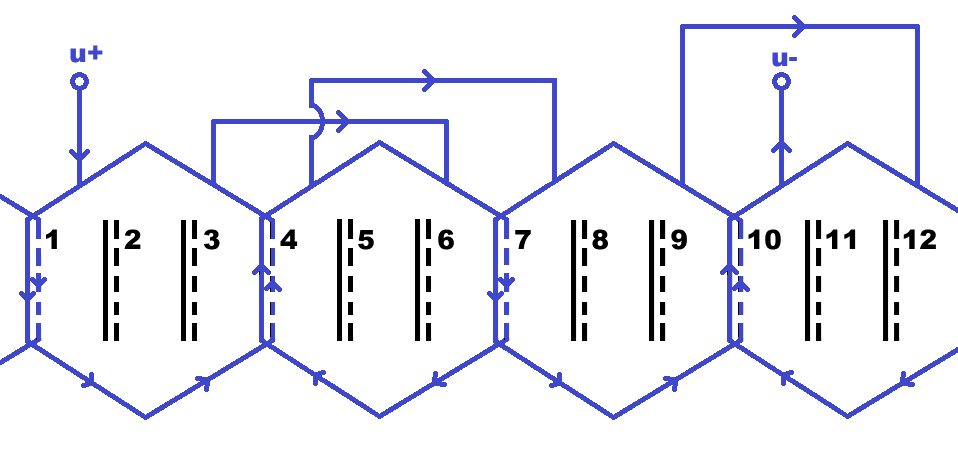

**Figure 1 **Winding schematic for my design that shows the connections of phase u.

Winding fill factor:

$k_{cu}=0.4$, because it is a distributed double-layer winding.

Largest current linkage will happen when $\alpha = 45^{\circ}$, so $\phi=90^{\circ}$.


$$\theta_m + 45 = \frac{\alpha_w+90}{2}$$


Expression for $\alpha_{w}$ in terms of the mechanical rotor angle:


$$\alpha_w = 2\cdot \theta_m$$


MATLAB Code Results:

p = 2; Q = 12; m = 3; q = Q/(2*p*m); yQ = m*q;
disp(['Slots per pole per phase, q = ', num2str(q)])

Slots per pole per phase, q = 1


disp(['Full pitch coil span, y_Q = ', num2str(yQ)])

Full pitch coil span, y_Q = 3


### Question 3

Finish the incomplete components of “Dependent and fixed variables,” “Allowable free variable range,” and “Constraints.” Do this by providing the following expressions:

#### Part (a)

Number of turns in a coil $z_Q$.

Answer:

Since I am using 18 AWG wire, which has a  and I chose my $k_{cu} = 0.4$, I can say that the number of turns in a coil for a double layer winding has to be


$$z_Q = \frac{k_{cu}S_u}{2\cdot S_c}$$


where $S_u = \frac{1}{2}\alpha_c(r_{o}^2-r_{i}^2)-w_{st}d_{st}$.

$r_o = r_s - d_{sy}$, and $r_i = r_o - d_{st}=r_s-d_{sy}-d_{st}$. I can substitute these to get:


$$S_u = \frac{1}{2}\alpha_c((r_s-d_{sy})^2-(r_s-d_{sy}-d_{st})^2)-w_{st}d_{st}$$



$$S_u = \frac{1}{2}\alpha_c(2(r_s-d_{sy})d_{st}-d_{st}^2)-w_{st}d_{st}$$



$$S_u = (\alpha_c(r_s-d_{sy})-w_{st})d_{st}-\frac{1}{2}\alpha_cd_{st}^2$$



$$S_u = (\frac{\pi}{6}(0.18-d_{sy})-w_{st})d_{st}-\frac{1}{2}\frac{\pi}{6}d_{st}^2$$


Extra notes:

#### Part (b)

Determine appropriate range for: $\alpha_{st}$

Thinking about this, the largest physically possible $\alpha_{st} = \frac{360}{Q} = \frac{360}{12} = 30^{\circ}$

However, there are a few constraints that need to be considered. Luckily, the script has been provided to me by the chief engineer. The final appropriate range for $\alpha_{st}$ is:

$1.8^{\circ}<\alpha_{st}<30^{\circ}$.

However, not every $\alpha_{st}$ will work for every design. So the check will need to be used when actually selecting an $\alpha_{st}$.

MATLAB Code Results:

alpha_st = deg2rad(0:0.1:30);

index_ast = NaN(length(alpha_st), length(wst), length(dst), length(dsy));

max_ast = NaN(length(wst), length(dst), length(dsy));
min_ast = NaN(length(wst), length(dst), length(dsy));

for j2 = 1:length(wst)
    for k2 = 1:length(dst)
        for l2 = 1:length(dsy)  
            for m2 = 1:length(alpha_st)
            index_ast(m2,j2,k2,l2) = checkToothTip(rs, dso, dsp, dst(k2), wst(j2), dsy(l2), alpha_st(m2));
            end
            if any(index_ast(:,j2,k2,l2) == 0)
                accept_ast = alpha_st(~logical(index_ast(:,j2,k2,l2)));
            end
            max_ast(j2,k2,l2) = max(accept_ast);
            min_ast(j2,k2,l2) = min(accept_ast);
        end
    end
end

min_ast_final = rad2deg(min(min_ast(:)));
max_ast_final = rad2deg(max(max_ast(:)));

disp(['Range of acceptable alpha_st: ', num2str(min_ast_final),' < alpha_st < ', num2str(max_ast_final)]);

#### Part (c)

Constraint equation to ensure acceptable tooth tip shape. Hint: This should be in terms of free variables $w_{st}$ and $\alpha_{st}$ and may include other free and dependent variables.

*Note: I am confused by this question! The code is provided in the folder.*


$$g(\alpha_{st}) = \frac{w_{st}}{2} -  \left( r_s - d_{sy} - d_{st} - d_{sp} \right) \cdot \sin\left( \frac{\alpha_{st}}{2} \right) \leq 0$$


### Question 4

Create an expression for active material cost (rotor and stator steel, rotor magnets, stator copper) in terms of the free and dependent variables that you will use to evaluate this objective. For the copper, please determine the length of magnet wire based on the same expression for length that we used for loss calculations.

### Question 5

Perform an initial analytic design of your motor to determine a set of values for the free variables that satisfy the allowable variable range and the constraint. Indicate the following information:

a. Selected magnetic loading, electric loading, and rotor volume

**Part (b)**

Number of turns in a coil

I found the bounds of the slot area and consequently the upper and lower bounds of the number of turns. MATLAB code is attached for reference.

$S_{u,upper}=6283.1853 mm^2$, $S_{u, lower} = 0~mm^2$

I am flooring to get the closest integer. This makes sure that my slot fill factor will not be higher than my estimate. Just my personal decision. Finally, the range of acceptable turns per coil is:

$0<z_Q<1526$ turns.

Interestingly and predictably, the max number of turns can be fitted when,


$$w_{st} = 5~mm, d_{st}=100~mm, d_{sy} = 5~mm$$


Just thinking about it, this will give the largest area for the turns.

MATLAB Code Results:

%% Slot fill factor
kcu = 0.4;         

%% Choice of wire
coil_AWG = 18;

Range of acceptable alpha_st: 1.8 < alpha_st < 30


dwire=0.324861*0.0254*exp(-0.115942*coil_AWG); % wire diameter in meters as a function of AWG
Sc = 0.25*pi*dwire^2;

%% Fixed variables
dso = 2;           %[mm]
dsp = 4;           %[mm]
rs = 180;          %[mm]

%% Allowable free range variables
delta = 1:1:5;
wst = 5:1:100;
dst = 5:1:100;
dsy = 5:1:50;

[wst_grid, dst_grid, dsy_grid] = ndgrid(wst, dst, dsy); 

%% Angle between slots
alpha_c = (2*pi)/Q; % [rad]

%% Slot area
% Calculation done in mm, so output will be mm^2.
Su = alpha_c*(rs-dsy_grid-wst_grid).*dst_grid - 0.5*alpha_c*dst_grid.^2;
% Upper bound
[Su_upper, position1] = max(Su(:)); 
[j1,k1,l1] = ind2sub(size(Su),position1);
% Lower bound
Su_lower = min(Su(:));
Su_lower = (Su_lower > 0)*Su_lower; % The minimum can be zero, that is why this line.

%% Turns per coil
% Upper bound
zQ_upper = floor((kcu*Su_upper*1e-6)/(2*Sc));
% Lower bound
zQ_lower = floor((kcu*Su_lower*1e-6)/(2*Sc));


disp(['Upper bound of stator slot area, S_u = ', num2str(Su_upper), ' mm^2. ', ...
    'The corresponding number of turns per coil, z_Q = ', num2str(zQ_upper)])

disp(['Lower bound of stator slot area, S_u = ', num2str(Su_lower), ' mm^2. ', ...
    'The corresponding number of turns per coil, z_Q = ', num2str(zQ_lower)])

c. The maximum field in the stator teeth

d. The maximum field in the stator yoke

e. All dimensions of the machine cross-section (free variables and the dependent variables)

### **Question 6**

Modify $evaluateDesign$ from HW3 by having it determine the required axial length to achieve a specified rated torque. Do this by performing the complete FEMM analysis of your machine with an axial length of 1mm, extract the field and torque values at each rotor location (just like you did in HW3, but now the length is 1mm), and then calculate the length required to obtain the rated torque. Use this newly calculated length for the loss calculations. The function should have the following function signature (the only differences are ratedTorque in Nm and the returned length in mm): function [designEval, length] = evaluateDesign(materials, dimensions, p, winding, settings, ratedTorque) I am providing you with an evaluateDesign.p file that has already implemented this which you can use in your optimization. You will receive extra credit if you create your own working evaluateDesign.m function.

### Question 7

Create a MATLAB function evaluateConstraints that will be called by MATLAB’s gamultiobj. This function is responsible for evaluating the design constraints. In addition to the constraints that I have indicated above, I am providing you with a MATLAB function checkToothTip which will indicate whether your free variables will yield valid tooth-tip geometry. The function returns 0 if the geometry is valid and 1 if the geometry is invalid. Use this function inside evaluateConstraints to constrain the optimization to valid geometry.